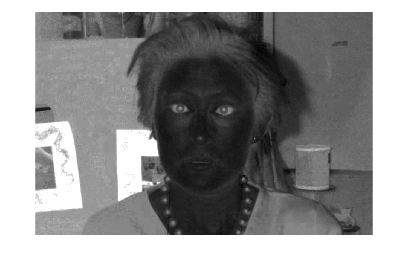


img = im2double(imread('..\DB2/cl_11.jpg'));

imgChrome = rgb2ycbcr(img);
%uint64(255 * mat2gray(grayImage))
Y = uint16(255 * mat2gray(imgChrome(:,:,1)));
Cb = uint16(255 * mat2gray(imgChrome(:,:,2)));
Cr = uint16(255 * mat2gray(imgChrome(:,:,3)));

Cr_neg = 255 - Cr;

EyeMapC = (1/3).*(Cb.^2 + Cr_neg.^2 + (Cb./Cr));

EyeMapC = im2double(EyeMapC);

imshow(EyeMapC, []) %Show 

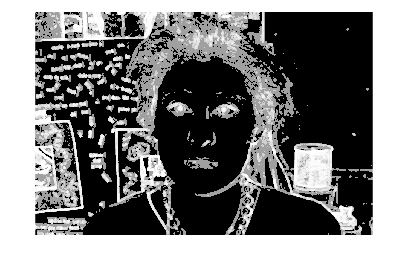


se = strel('disk', 4);

EyeMapL = imdilate(Y, se) ./ (imerode(Y, se) + 1);

EyeMapL = im2double(histeq(EyeMapL));

imshow(EyeMapL, [])

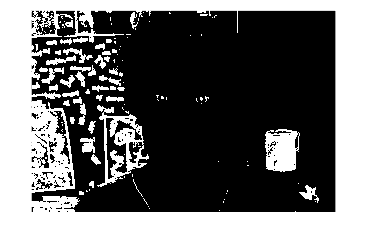


EyeMap = EyeMapL.*EyeMapC;
EyeMap = histeq(EyeMap);

EyeMap = EyeMap > 0.85;

imshow(EyeMap,[])